## 8.2.3 拓展：用到函数句柄的一些新的内置函数

### arrayfun: 对数组中的每个元素应用同一个函数

f = @(x) x^2-2*x+5;
x = [1 4 5];
% f(x)

f = @(x) x^2-2*x+5;
x = [1 4 5];
y1 = arrayfun(f,x)

f = @(x) x^2-2*x+5;
x = [1 4 5];
y2 = x;
for ii = 1:numel(x)
    y2(ii) = f(x(ii));
end
y2

c = arrayfun(@(x) randi(10,x,x), 1:3,'UniformOutput',0);
celldisp(c)
D = blkdiag(c{:})

c = arrayfun(@(x) randi(10,x,x), 1:10,'UniformOutput',0);
celldisp(c)
D = blkdiag(c{:})

c = cell(1,3);
for ii = 1:3
    c{ii} = randi(10,ii,ii);
end
% celldisp(c)
D = blkdiag(c{:})

冰雹猜想 3n+1猜想

v = zeros(1,100);
for n = 1:100
    v(n) = hailstone1(n);
end
v

v = arrayfun(@hailstone1, 1:100)

hailstone2(5)
hailstone2(20)

C = cell(100,1);
for n = 1:100
    C{n} = hailstone2(n);
end
C

% C = arrayfun(@hailstone2, 1:100)

C = arrayfun(@hailstone2, 1:100, ...
             'UniformOutput',0);
C'

C = {1:9, [2; 4; 6; 8], []};
n1 = cellfun(@numel,C)
n2 = arrayfun(@numel,C)

### **structfun****: ****对标量结构体的每个字段的值应用同一个函数**

S.f1 = 1:9;
S.f2 = [5; 8; 11];
S.f3 = [1 NaN 3 5];
S
d1 = structfun(@mean,S)
d2 = structfun(@(x) mean(x,'omitnan'),S)

% S1 = structfun(@sort ,S)

S2 = structfun(@sort ,S,'UniformOutput',false)

clear
S(1).name = '清风';
S(1).score = [90 80 100];
S(2).name = '小李';
S(2).score = [70 80 90];
S(3).name = '小张';
S(3).score = [60 80 70];
S

**structfun****函数不能用于非标量结构体**

% structfun(@mean,S)

arrayfun(@(x) mean(x.score), S)
y = zeros(1,numel(S));
for ii = 1:numel(S)
    y(ii) = mean(S(ii).score);
end
y

close all; clear all
x = [0,2*pi];
hold on
p.l1 = fplot(@sin,x,'r');
p.l2 = fplot(@cos,x,'b');
p.l3 = fplot(@(x) sin(x).*cos(x),x,'k');
hold off
structfun(@(x) set(x,'LineWidth',1.5), p)
xticks(0:pi/2:2*pi)
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi'})

### integral 计算一元函数的定积分 

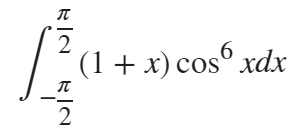

f = @(x) (1+x) .* (cos(x)).^ 6;
% f = @(qf) (1+qf).*(cos(qf)).^6;
d = integral(f,-pi/2,pi/2)  % 数值解
5/16*pi  % 这道题的解析解

.*不能改成*

% f = @(x) (1+x) * (cos(x)).^6;
% d = integral(f,-pi/2,pi/2)

d = integral(@intefun1, -pi/2, pi/2)

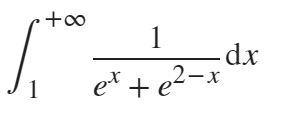

f = @(x) 1 ./ (exp(x)+exp(2-x));
d = integral(f,1,inf)  % 数值解
pi/4/exp(1)  % 这道题的解析解

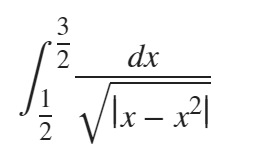

format long g
pi/2+log(sqrt(3)+2) % 这道题的解析解
f = @(x) 1 ./ sqrt(abs(x-x.^2));
d1 = integral(f,1/2,3/2) 
d2 = integral(f,1/2,3/2, ...
        'AbsTol',1e-16, 'RelTol',1e-10)

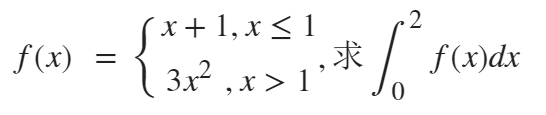

d1 = integral(@(x) x+1,0,1)
d2 = integral(@(x) 3*x.^2,1,2)
d1 + d2

f = @(x) (x>1).*(3*x.^2) + (x<=1).*(x+1);
d = integral(f,0,2)

integral(@intefun2,0,2)

integral(@(x) x+1 ,0,2)

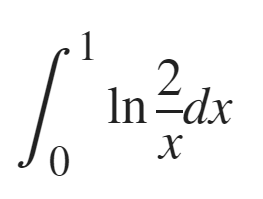

format long g
log(2)+1  % 这道题的解析解
f = @(x) log(2./x);
d1 = integral(f,0,1) 
d2 = integral(f,0,1, ...
              'AbsTol',1e-16, ...
              'RelTol',1e-10)
d3 = integral(f,0,1, ...
              'AbsTol',1e-20, ...
              'RelTol',1e-16)

format short

**参数化函数的定积分**

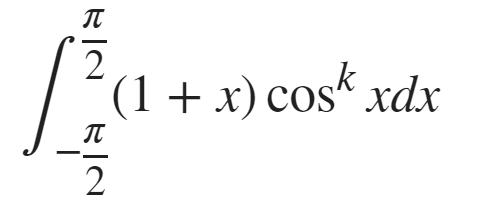

k = 6;
f = @(x) (1+x) .* (cos(x)).^ k;
integral(f,-pi/2,pi/2) 
k = 5;
integral(f,-pi/2,pi/2) 

k = 5;
f = @(x) (1+x) .* (cos(x)).^ k;
integral(f,-pi/2,pi/2) 

k = 3;
d = integral(@(x) (1+x) .* (cos(x)).^ k,-pi/2,pi/2)
k = 5;
d = integral(@(x) (1+x) .* (cos(x)).^ k,-pi/2,pi/2)

f = @(x,k) (1+x) .* (cos(x)).^ k;
% integral(f, -pi/2, pi/2)
% integral(f(x,k), -pi/2, pi/2)
% integral(f(x,5), -pi/2, pi/2)
% integral(@f, -pi/2, pi/2)

f = @(x,k) (1+x) .* (cos(x)).^ k;
k = 3;
g = @(x) f(x,k);
integral(g, -pi/2, pi/2)
integral(@(x) f(x,3), -pi/2, pi/2)

f = @(k) integral(@(x) (1+x) .* (cos(x)).^ k,  -pi/2, pi/2);
f(3)
f(6)

inte_test(3)
inte_test(6)

arrayfun(@inte_test,1:10)

f = @(k) integral(@(x) (1+x) .* (cos(x)).^ k,  -pi/2, pi/2);
arrayfun(f,1:10)

k = (1:10)';
f = @(x) (1+x) .* (cos(x)).^ k;
integral(f, -pi/2, pi/2,'ArrayValued',1)

### **integral2 计算二重积分（数值积分） **

format long g
f = @(x,y) (x.*y)./(1+y);
d1 = integral2(f,0,1,0,2)  % 数值解

d1 =          0.450693855675585


1-log(3)/2  % 解析解

ans =          0.450693855665945


d2 = integral2(f,0,1,0,2, ...
      'AbsTol',1e-20,'RelTol',1e-20) % 减小误差容限

d2 =          0.450693855665945


f2 = @(y,x) (x.*y)./(1+y);
d = integral2(f2,0,2,0,1)

format short
f = @(theta,r) sqrt(1-r.^2.*cos(2*theta)) .* r.^2 .*sin(theta);
r_ub = @(theta) 1./cos(theta);  % r的上界
integral2(f,0,pi/4,0,r_ub)  % 数值解

ans = 0.1370

1/3-pi/16   % 解析解

ans = 0.1370

% f = @(r,theta) sqrt(1-r.^2.*cos(2*theta)) .* r.^2 .*sin(theta);
% r_ub = @(theta) 1./cos(theta);  % r的上界
% integral2(f,0,r_ub,0,pi/4)  % 数值解

f = @(y,x) exp(x.^2)./x - exp(y.^2);
integral2(f,0,1,@(y) y,1)  % 数值解

ans = 0.8591

(exp(1)-1)/2   % 解析解

ans = 0.8591

f = @(y,x) x .* sin(y) ./ y;
integral2(f, 0, 1, @(y) y.^2, @(y) y)  % 数值解

ans = 0.0620

2*sin(1)-3*cos(1)   % 解析解

ans = 0.0620

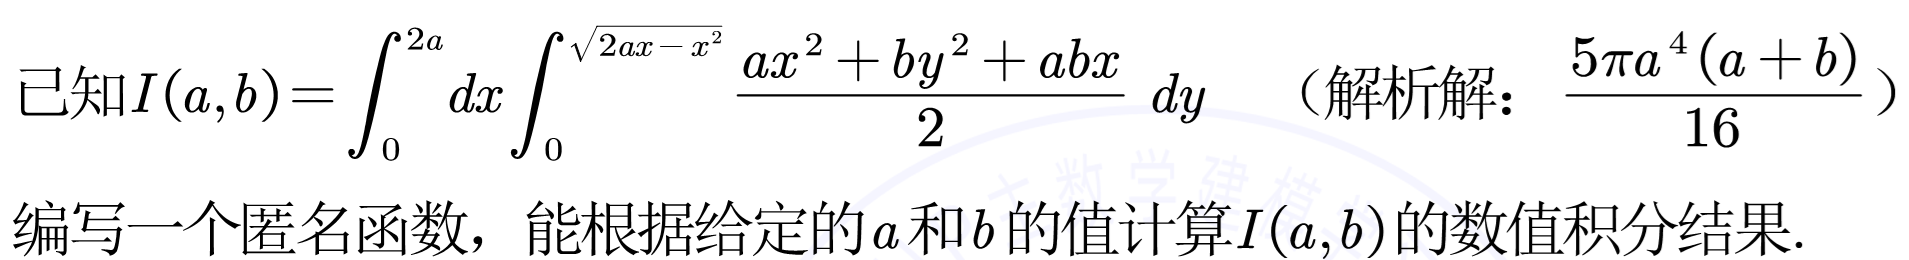

f = @(a,b) integral2(@(x,y) (a*x.^2+b*y.^2+a*b*x)/2, 0,2*a,0,@(x) sqrt(2*a*x-x.^2));
a = 3;
b = -3;
f(a,b)

ans = 3.4417e-15

5*pi*a^4*(a+b)/16

ans = 0

### **fminbnd 求解一元函数在给定区间上的最小值 **

**回顾：使用网格搜索法求一元函数的最小值问题**

f1 = @(x) (x-2).^2+5;
x_min = grid_search(f1, 0, 4, 0.01)

x_min = 2

f2 = @sin;
[x_min, f_min] = grid_search(f2, 0, 2*pi, 0.01)

x_min = 4.7100

f_min = -1.0000

x = (1:10)';
y = [9.3 19 28.6 39 48.5 60.9 71 79.8 90 102]';
f3 = @(k) sum((y-k.*x).^2);  % 拟合y = k*x
[k_min, f_min] = grid_search(f3, 0, 20, 0.1)

k_min = 10

f_min = 12.5500

f = @(x) -(2*x-exp(x));
[x, ff] = grid_search(f, 0, 1, 0.0001)
f_max = -ff

f1 = @cos;
[x1,fval1] = fminbnd(f1,0,2*pi)

x1 = 3.1416

fval1 = -1

f2 = @(x) sin(2*x)*cos(x/3);
[x2,fval2] = fminbnd(f2,0,4*pi)

x2 = 10.1885

fval2 = -0.9669

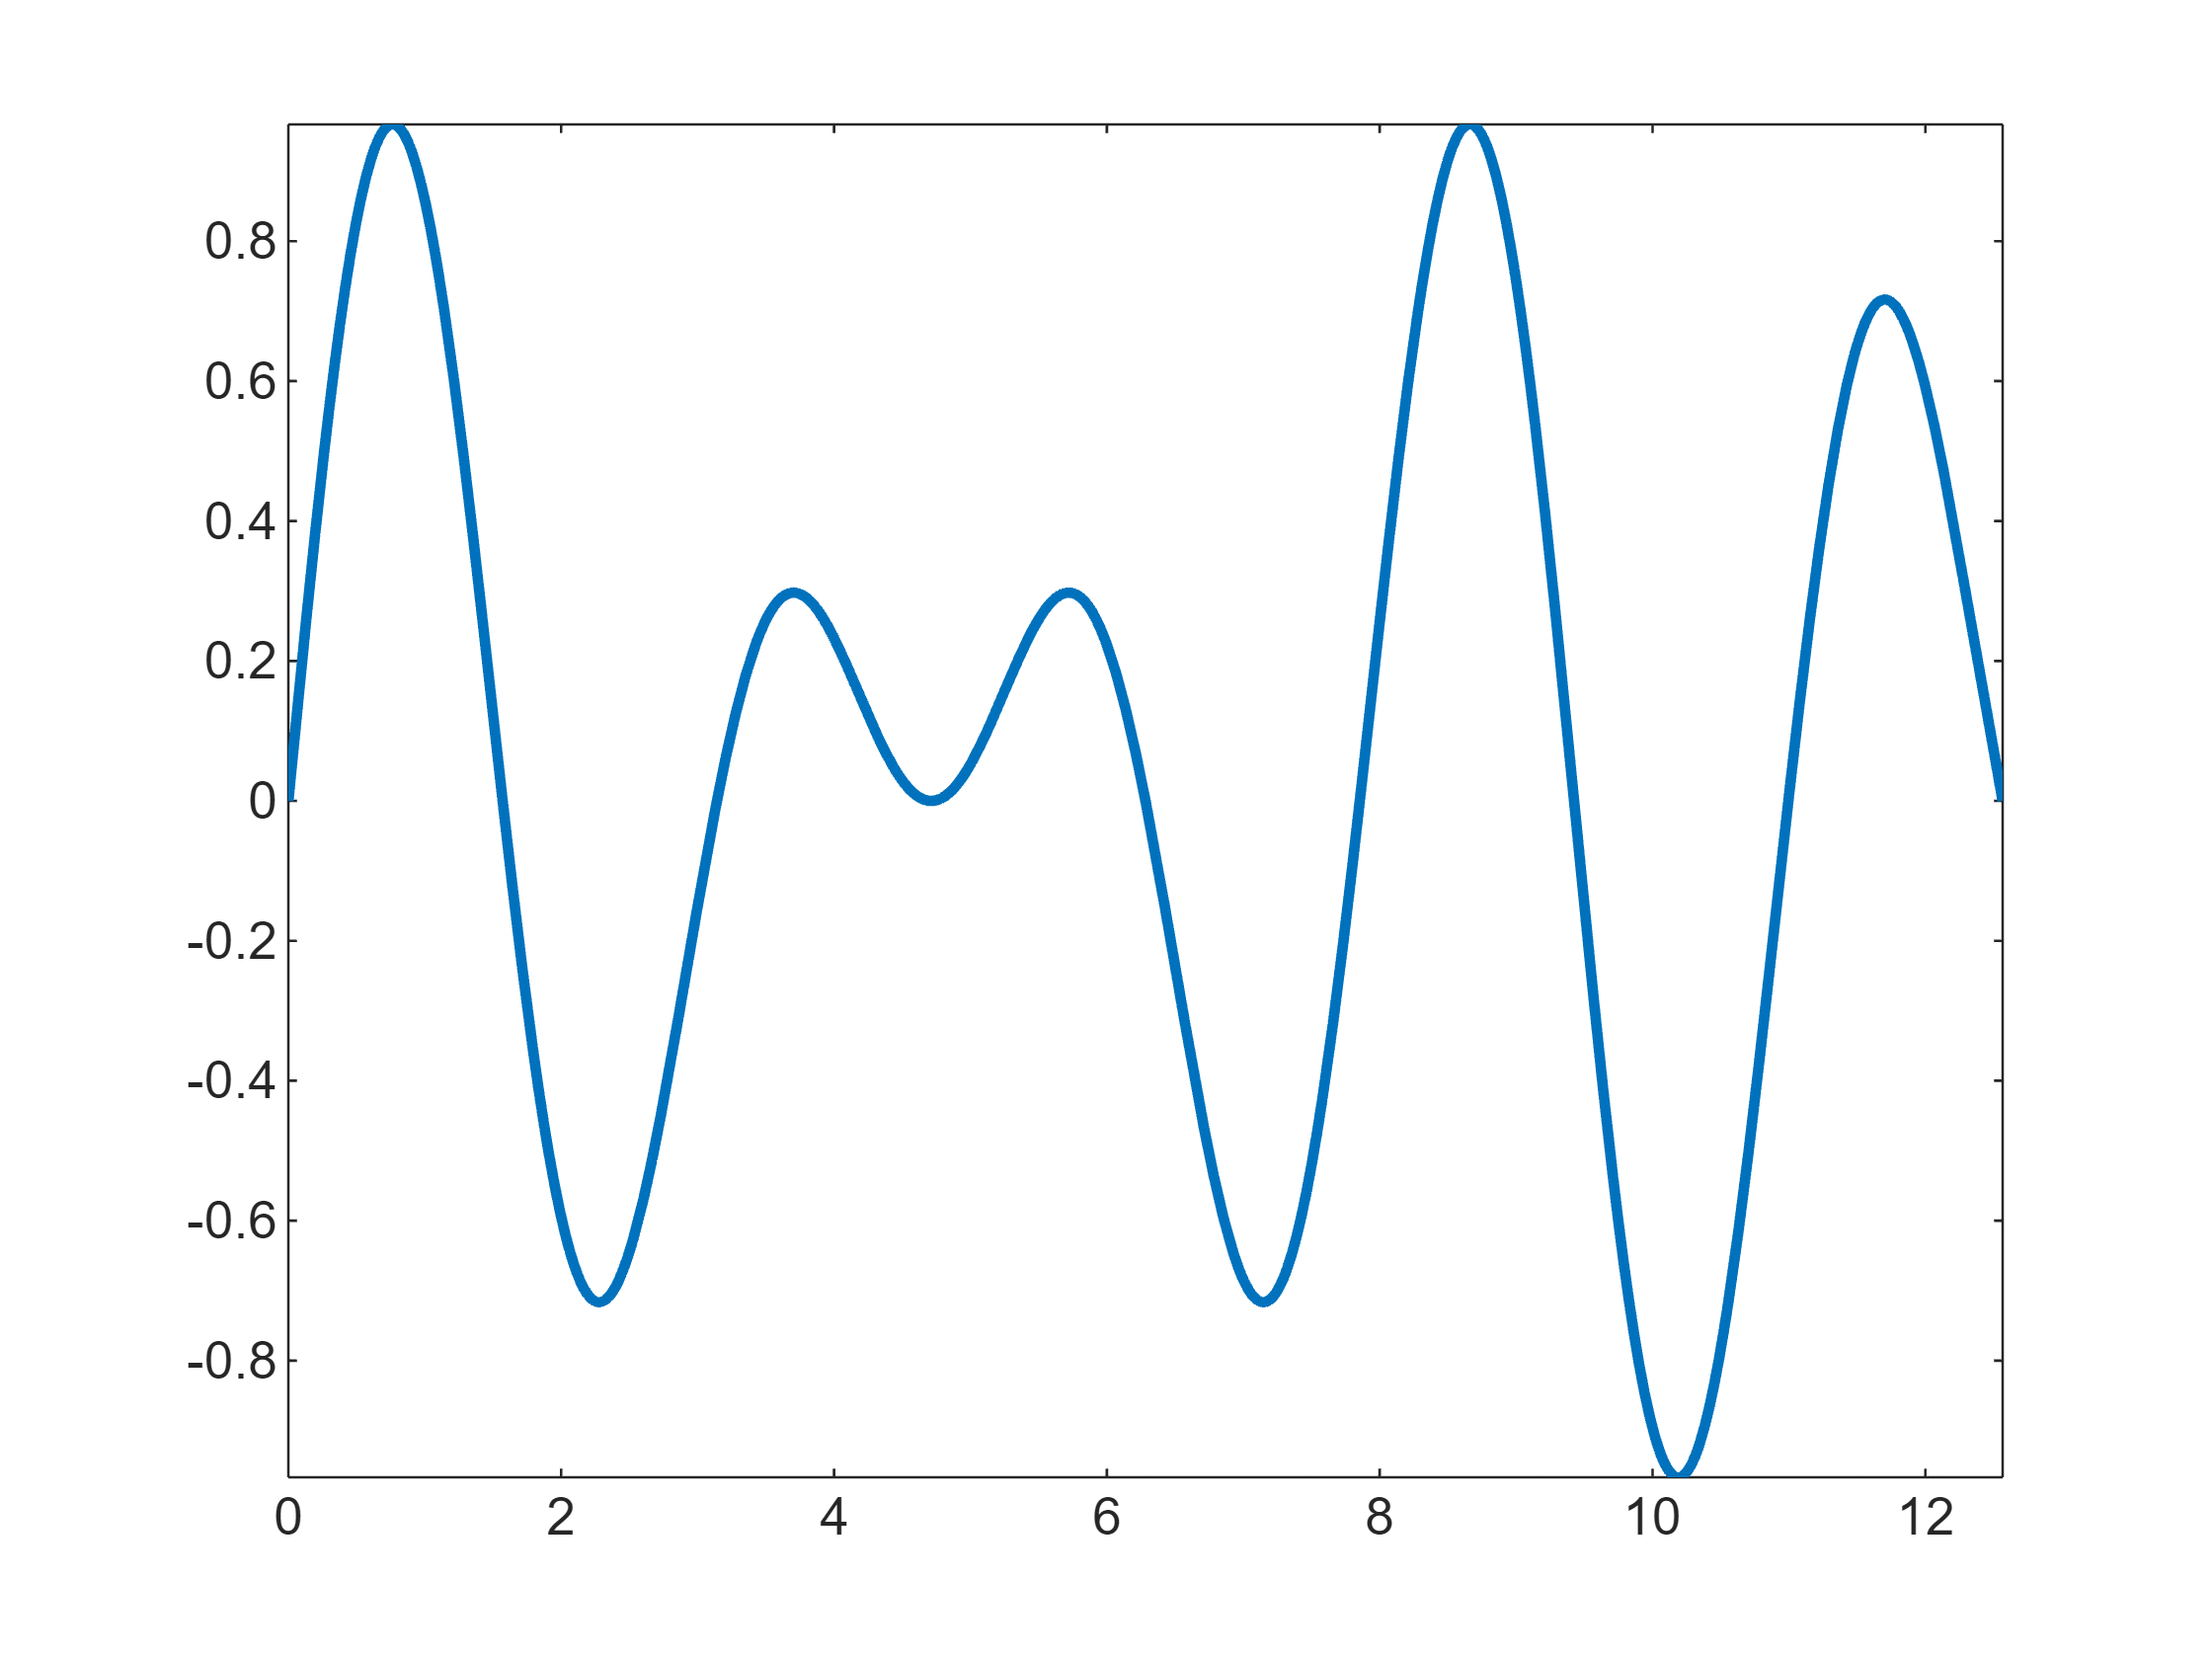

% close all
% f = @(x) sin(2*x).*cos(x/3);
% fplot(f,[0,4*pi],'LineWidth',2)

下一章会介绍MATLAB的绘图功能

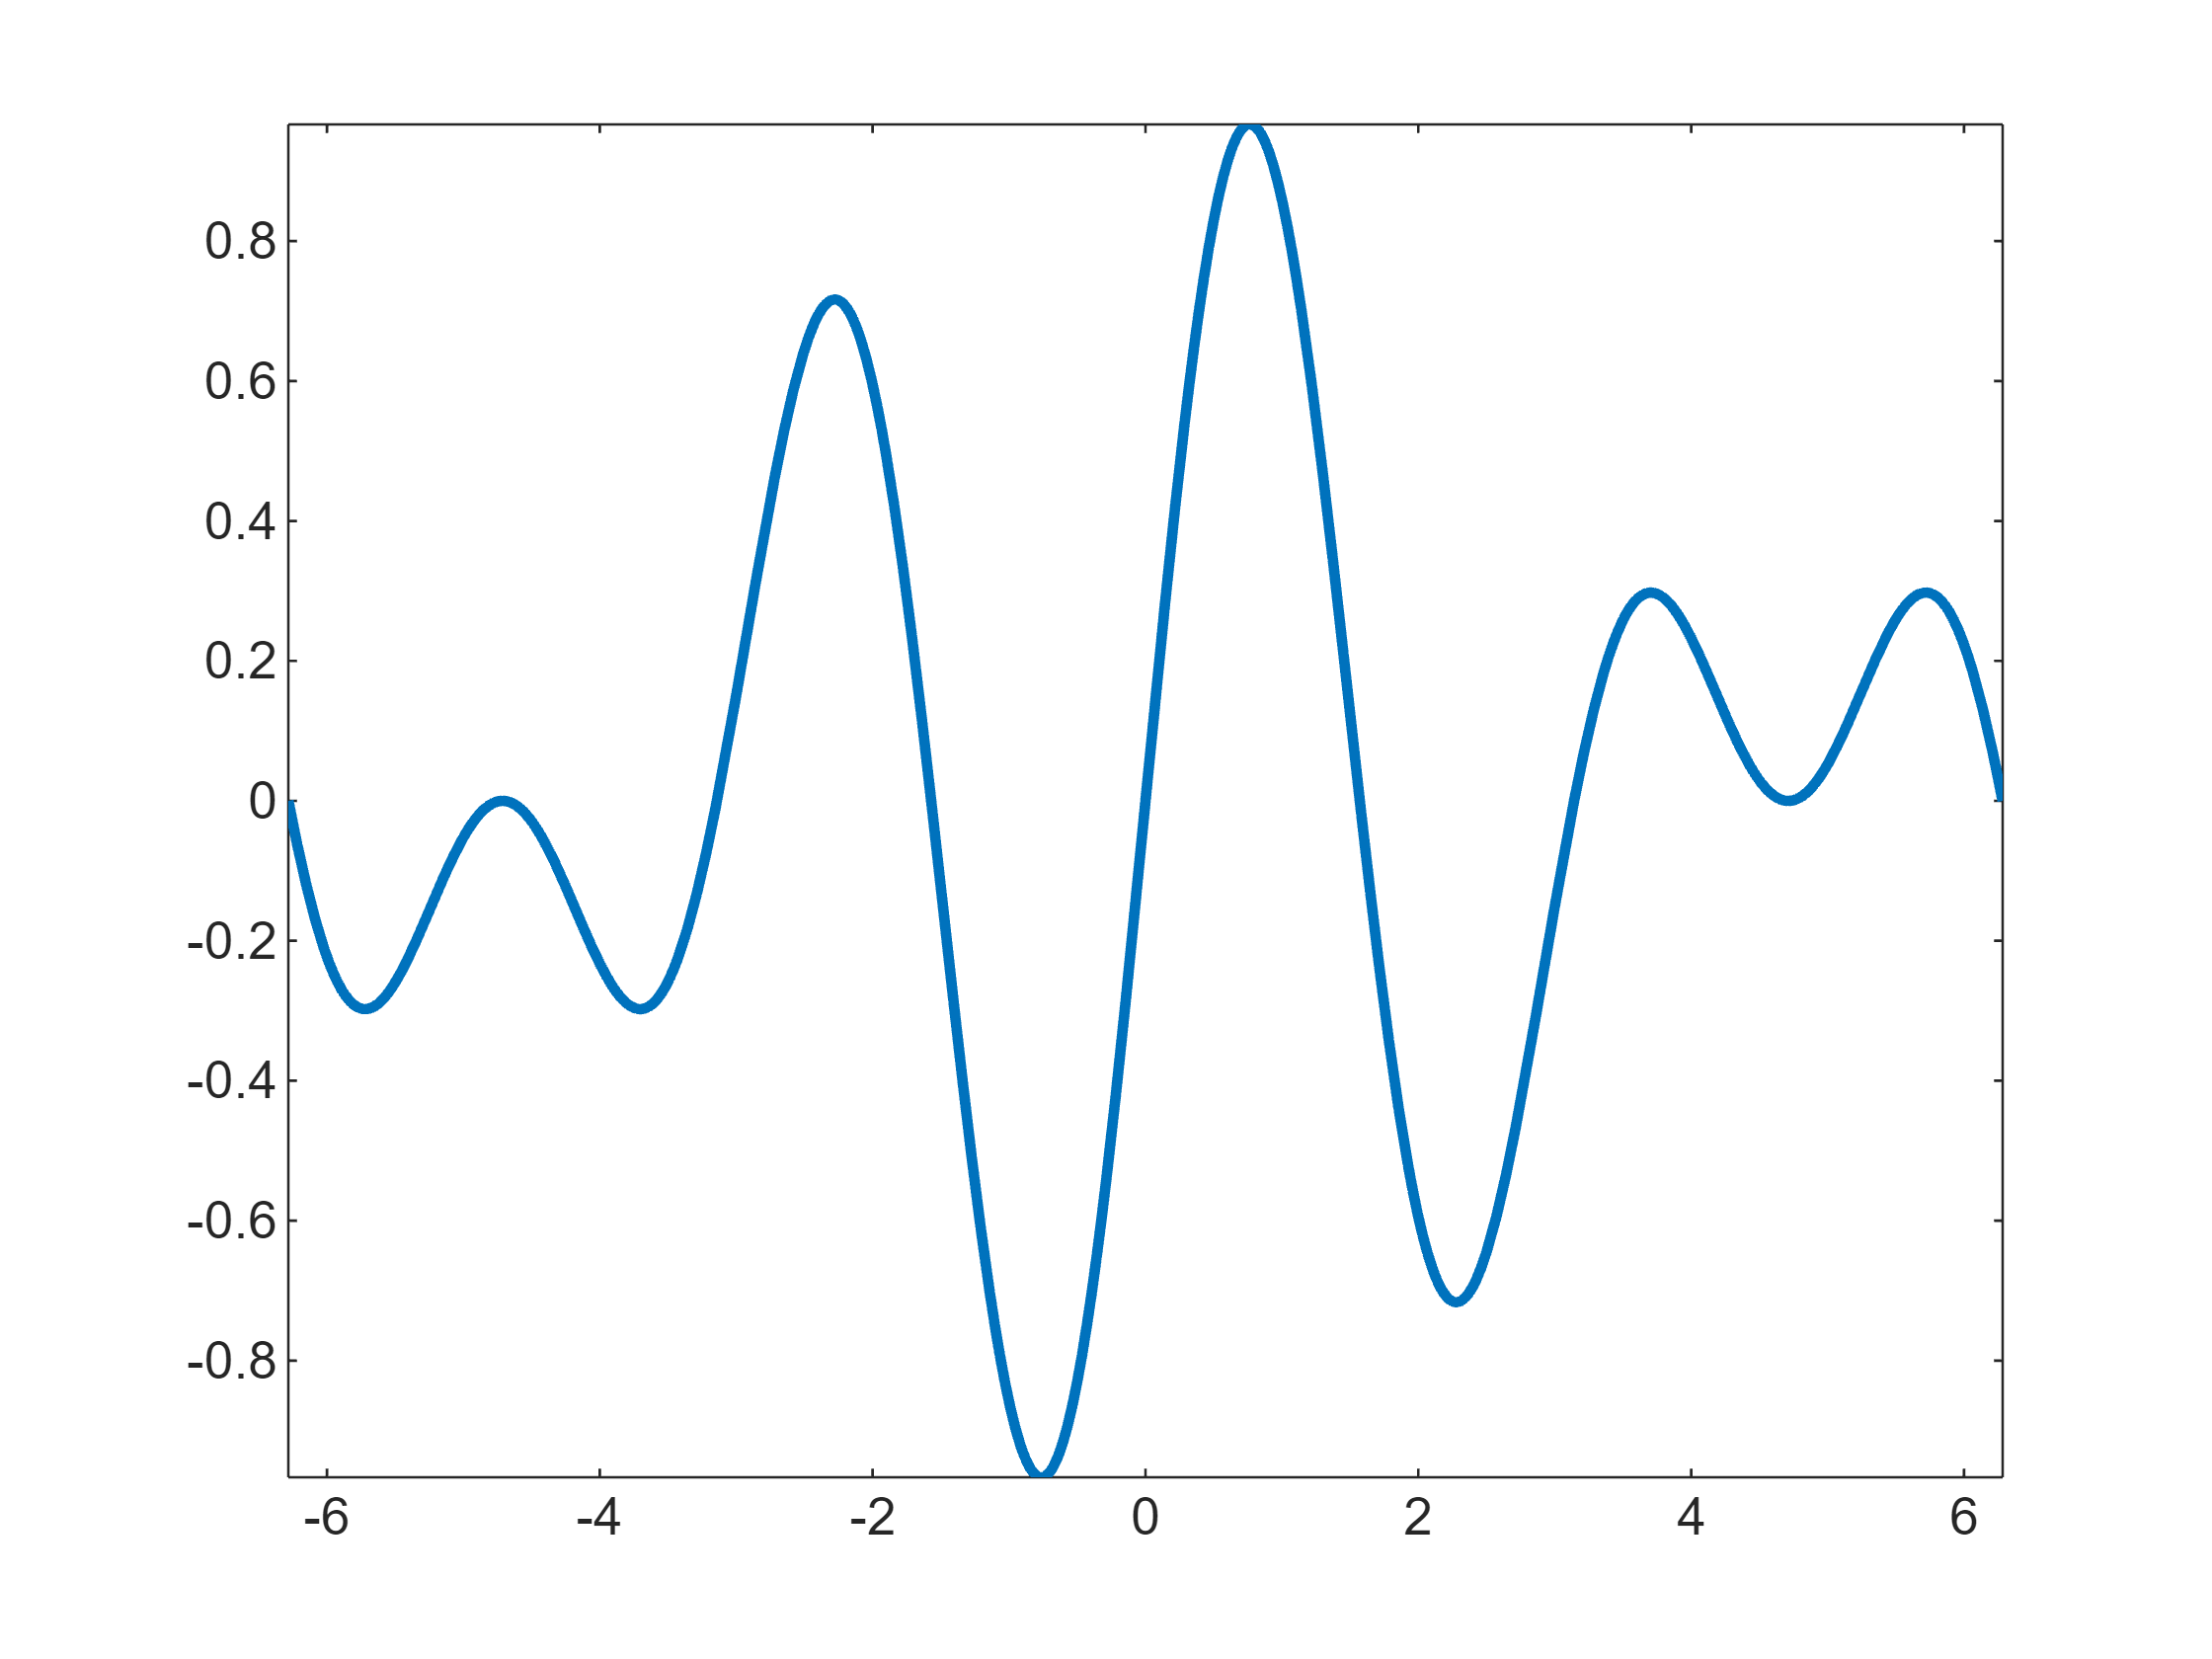

close all
f = @(x) sin(2*x).*cos(x/3);
fplot(f,[-2*pi,2*pi],'LineWidth',2)

f = @(x) sin(2*x).*cos(x/3);
[x,fval] = fminbnd(f,-2*pi,2*pi)
[x,fval] = fminbnd(f,-2,0)

g = @(x) -sin(2*x).*cos(x/3);
[x,fval] = fminbnd(g,-2*pi,2*pi)
[x,fval] = fminbnd(g,0,2) 
fval = -fval

### **fminsearch 对多元函数的最小值 **

f = @(x) sin(2*x).*cos(x/3);
[x,fval] = fminsearch(f,0)

f = @(x) sin(2*x).*cos(x/3);
[x,fval] = fminsearch(f,1)
[x,fval] = fminsearch(f,-3)

% f = @(x,y) (x-1).^2 + (y-1).^2 ;
% [xy,fval] = fminsearch(f,[0,0])

% 它接受一个向量x，其中x(1)代表x，x(2)代表y
f = @(x) (x(1)-1).^2 + (x(2)-2).^2;
[x,fval] = fminsearch(f,[0,0])

x =     1.0000    2.0000


fval = 1.8692e-09

f = @(x) (x(1)-x(2)+1).^2 + ...
         (x(2)-x(3)+1).^2 + ...
         abs(x(3)-3);
[x,fval] = fminsearch(f,[0,0,0])

x =     1.0000    2.0000    3.0000


fval = 2.5503e-09

f = @(x) (x(1)-x(2)+1).^2 + ...
         (x(2)-x(3)+1).^2 + ...
         abs(x(3)-3);
[x,fval] = fminsearch(f,[10,0,0])

x =    -1.5846   -0.5846    0.6843


fval = 2.3880

**测试函数****Sphere**

  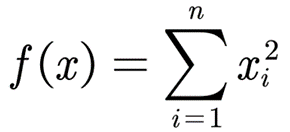

f = @(x) sum(x.^2);
x0 = rand(1,10);  % 初始值 指定为01区间上的10个随机数
[x,fval] = fminsearch(f,x0)

f = @(x) sum(x.^2);
x0 = rand(1,10);  % 初始值 指定为01区间上的10个随机数
options = optimset('MaxFunEvals',10000);
[x,fval] = fminsearch(f,x0,options)

x0 = rand(1,10);  % 初始值 指定为01区间上的10个随机数
options = optimset('MaxFunEvals',10000,'MaxIter',10000);
[x,fval] = fminsearch('Rosenbrock',x0,options)

f = @(x) x(1).^2+x(2).^2+10*sin(x(1))+10*cos(x(2));
[x, fval] = fminsearch(f, [0 0])

x =    -1.3064    2.5957


fval = -9.7548

fval = -fval % 最大值

fval = 9.7548

绘图内容会在下一章介绍

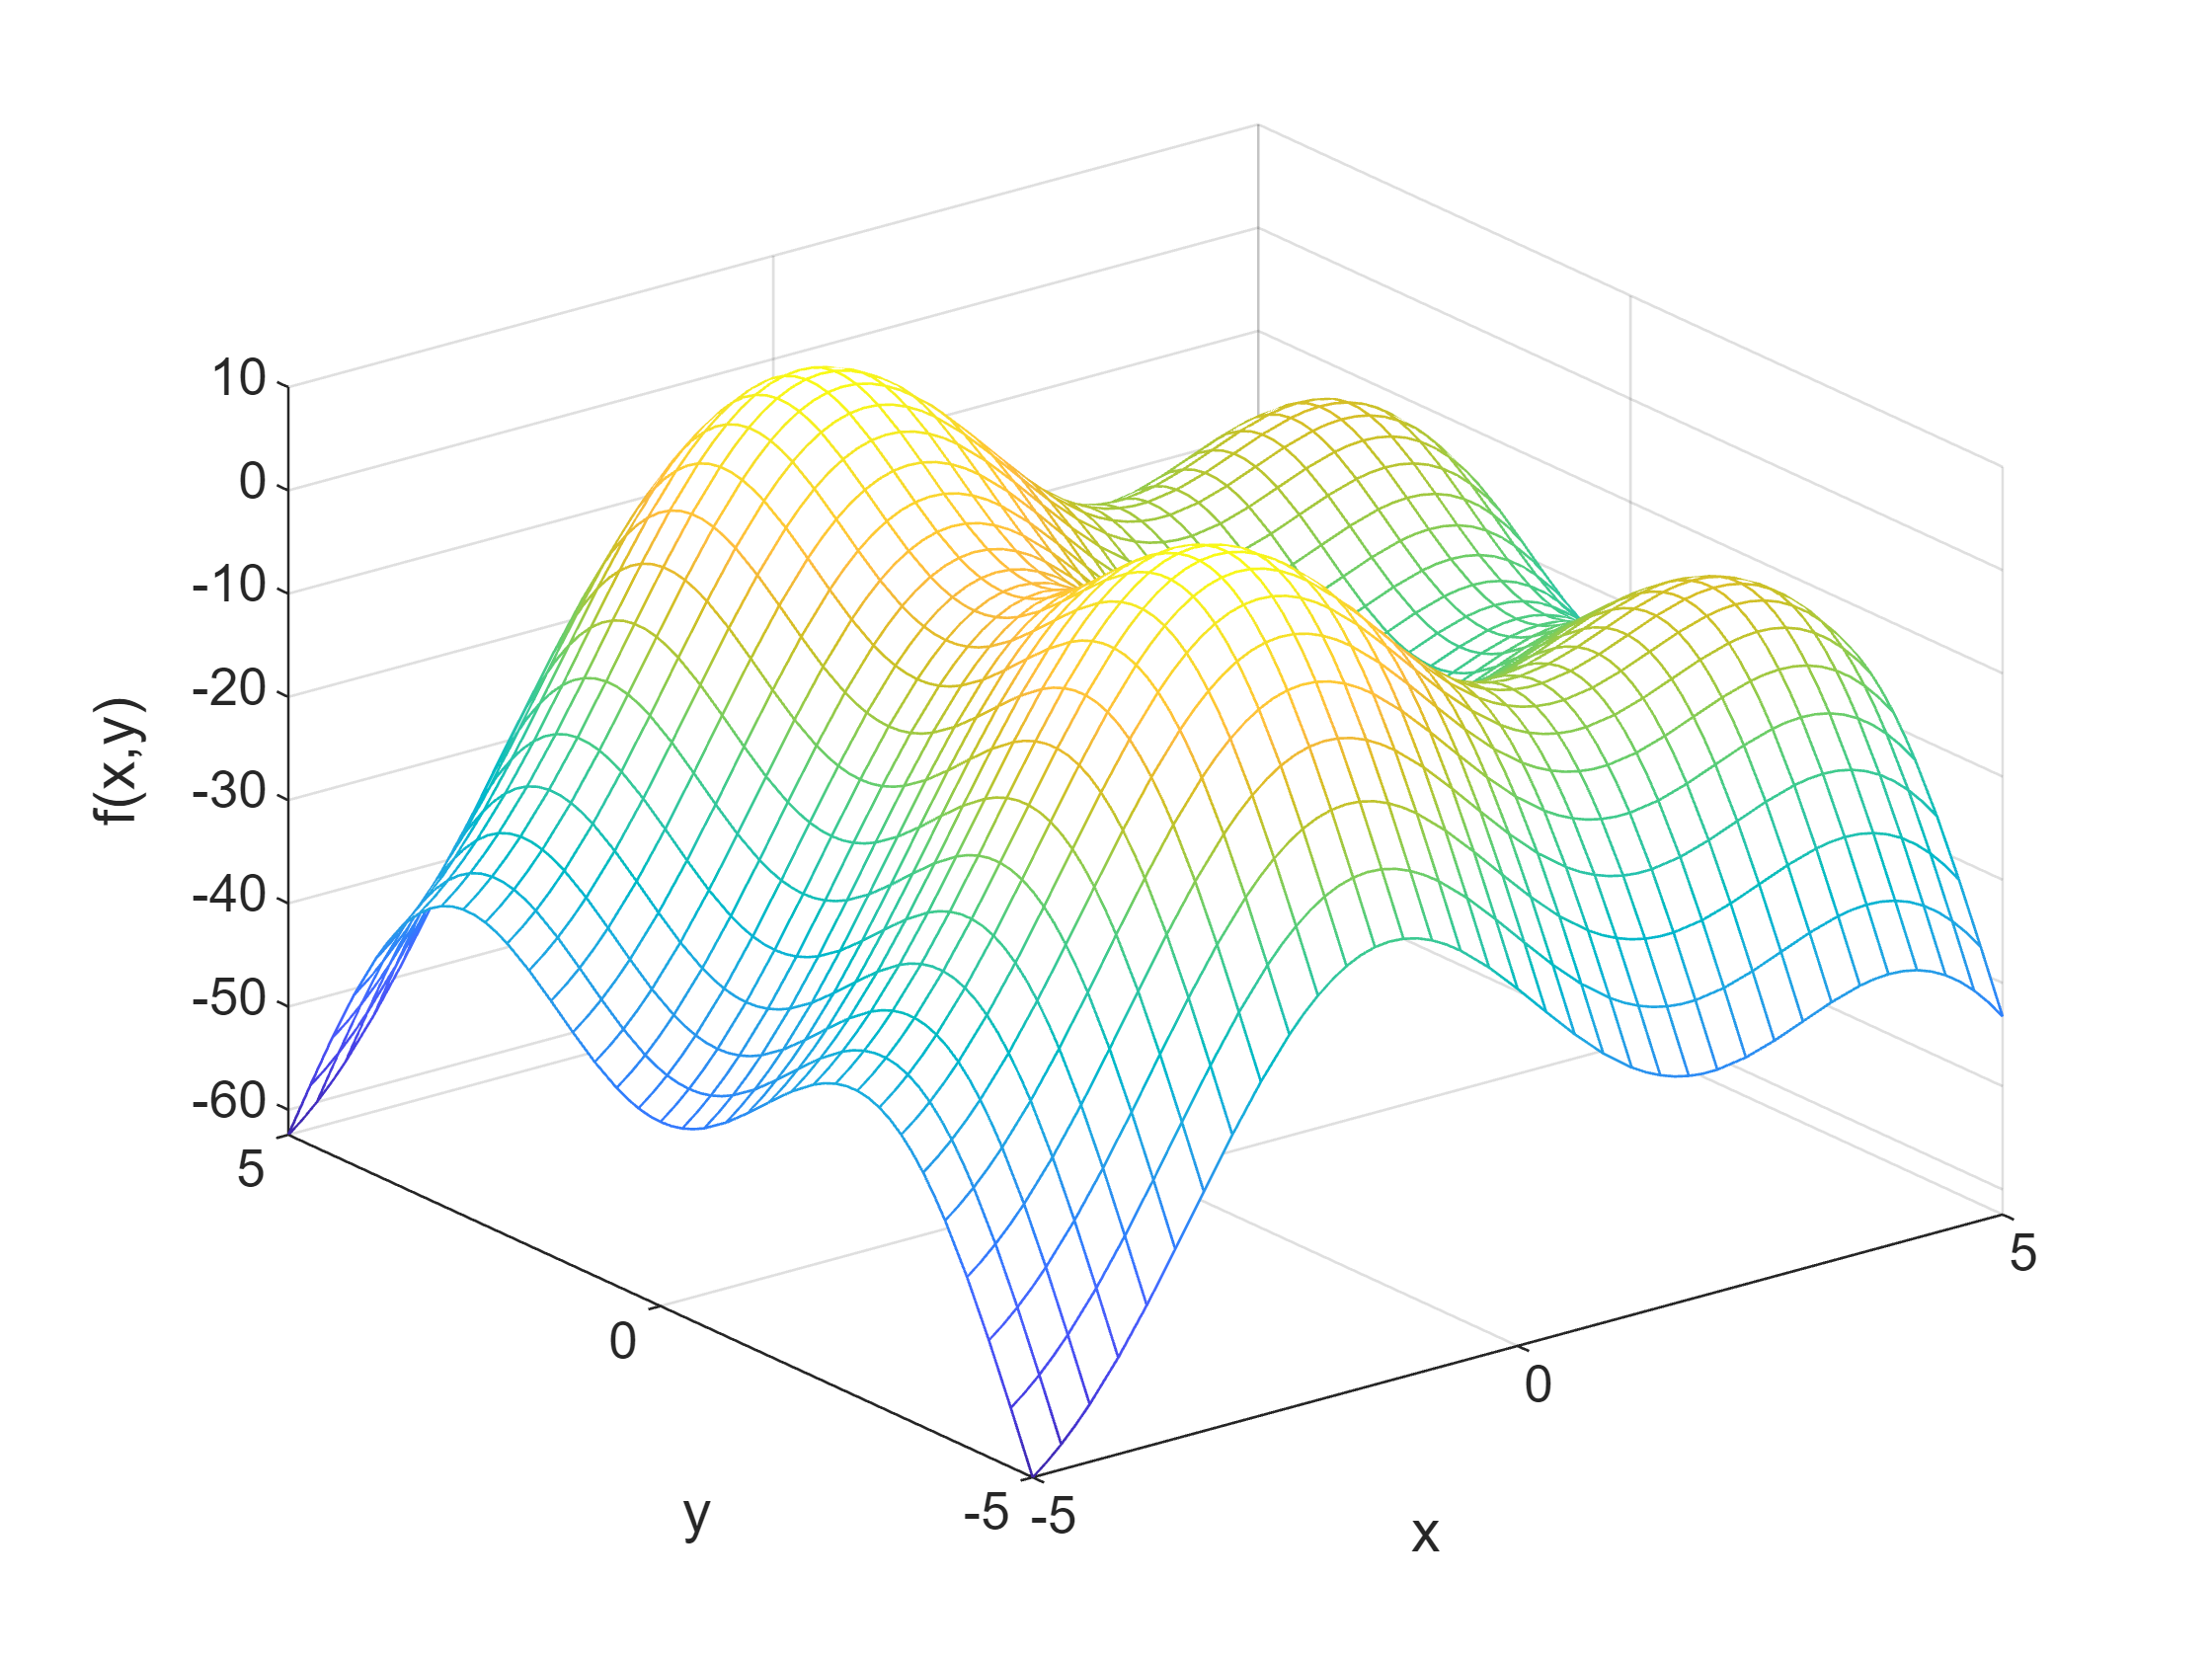

originalFun = @(x, y) -(x.^2 + y.^2 + 10.*sin(x) + 10.*cos(y));
fmesh(originalFun)
xlabel('x')
ylabel('y')
zlabel('f(x,y)')

### fzero 求一元函数等于0的根(函数的零点) 

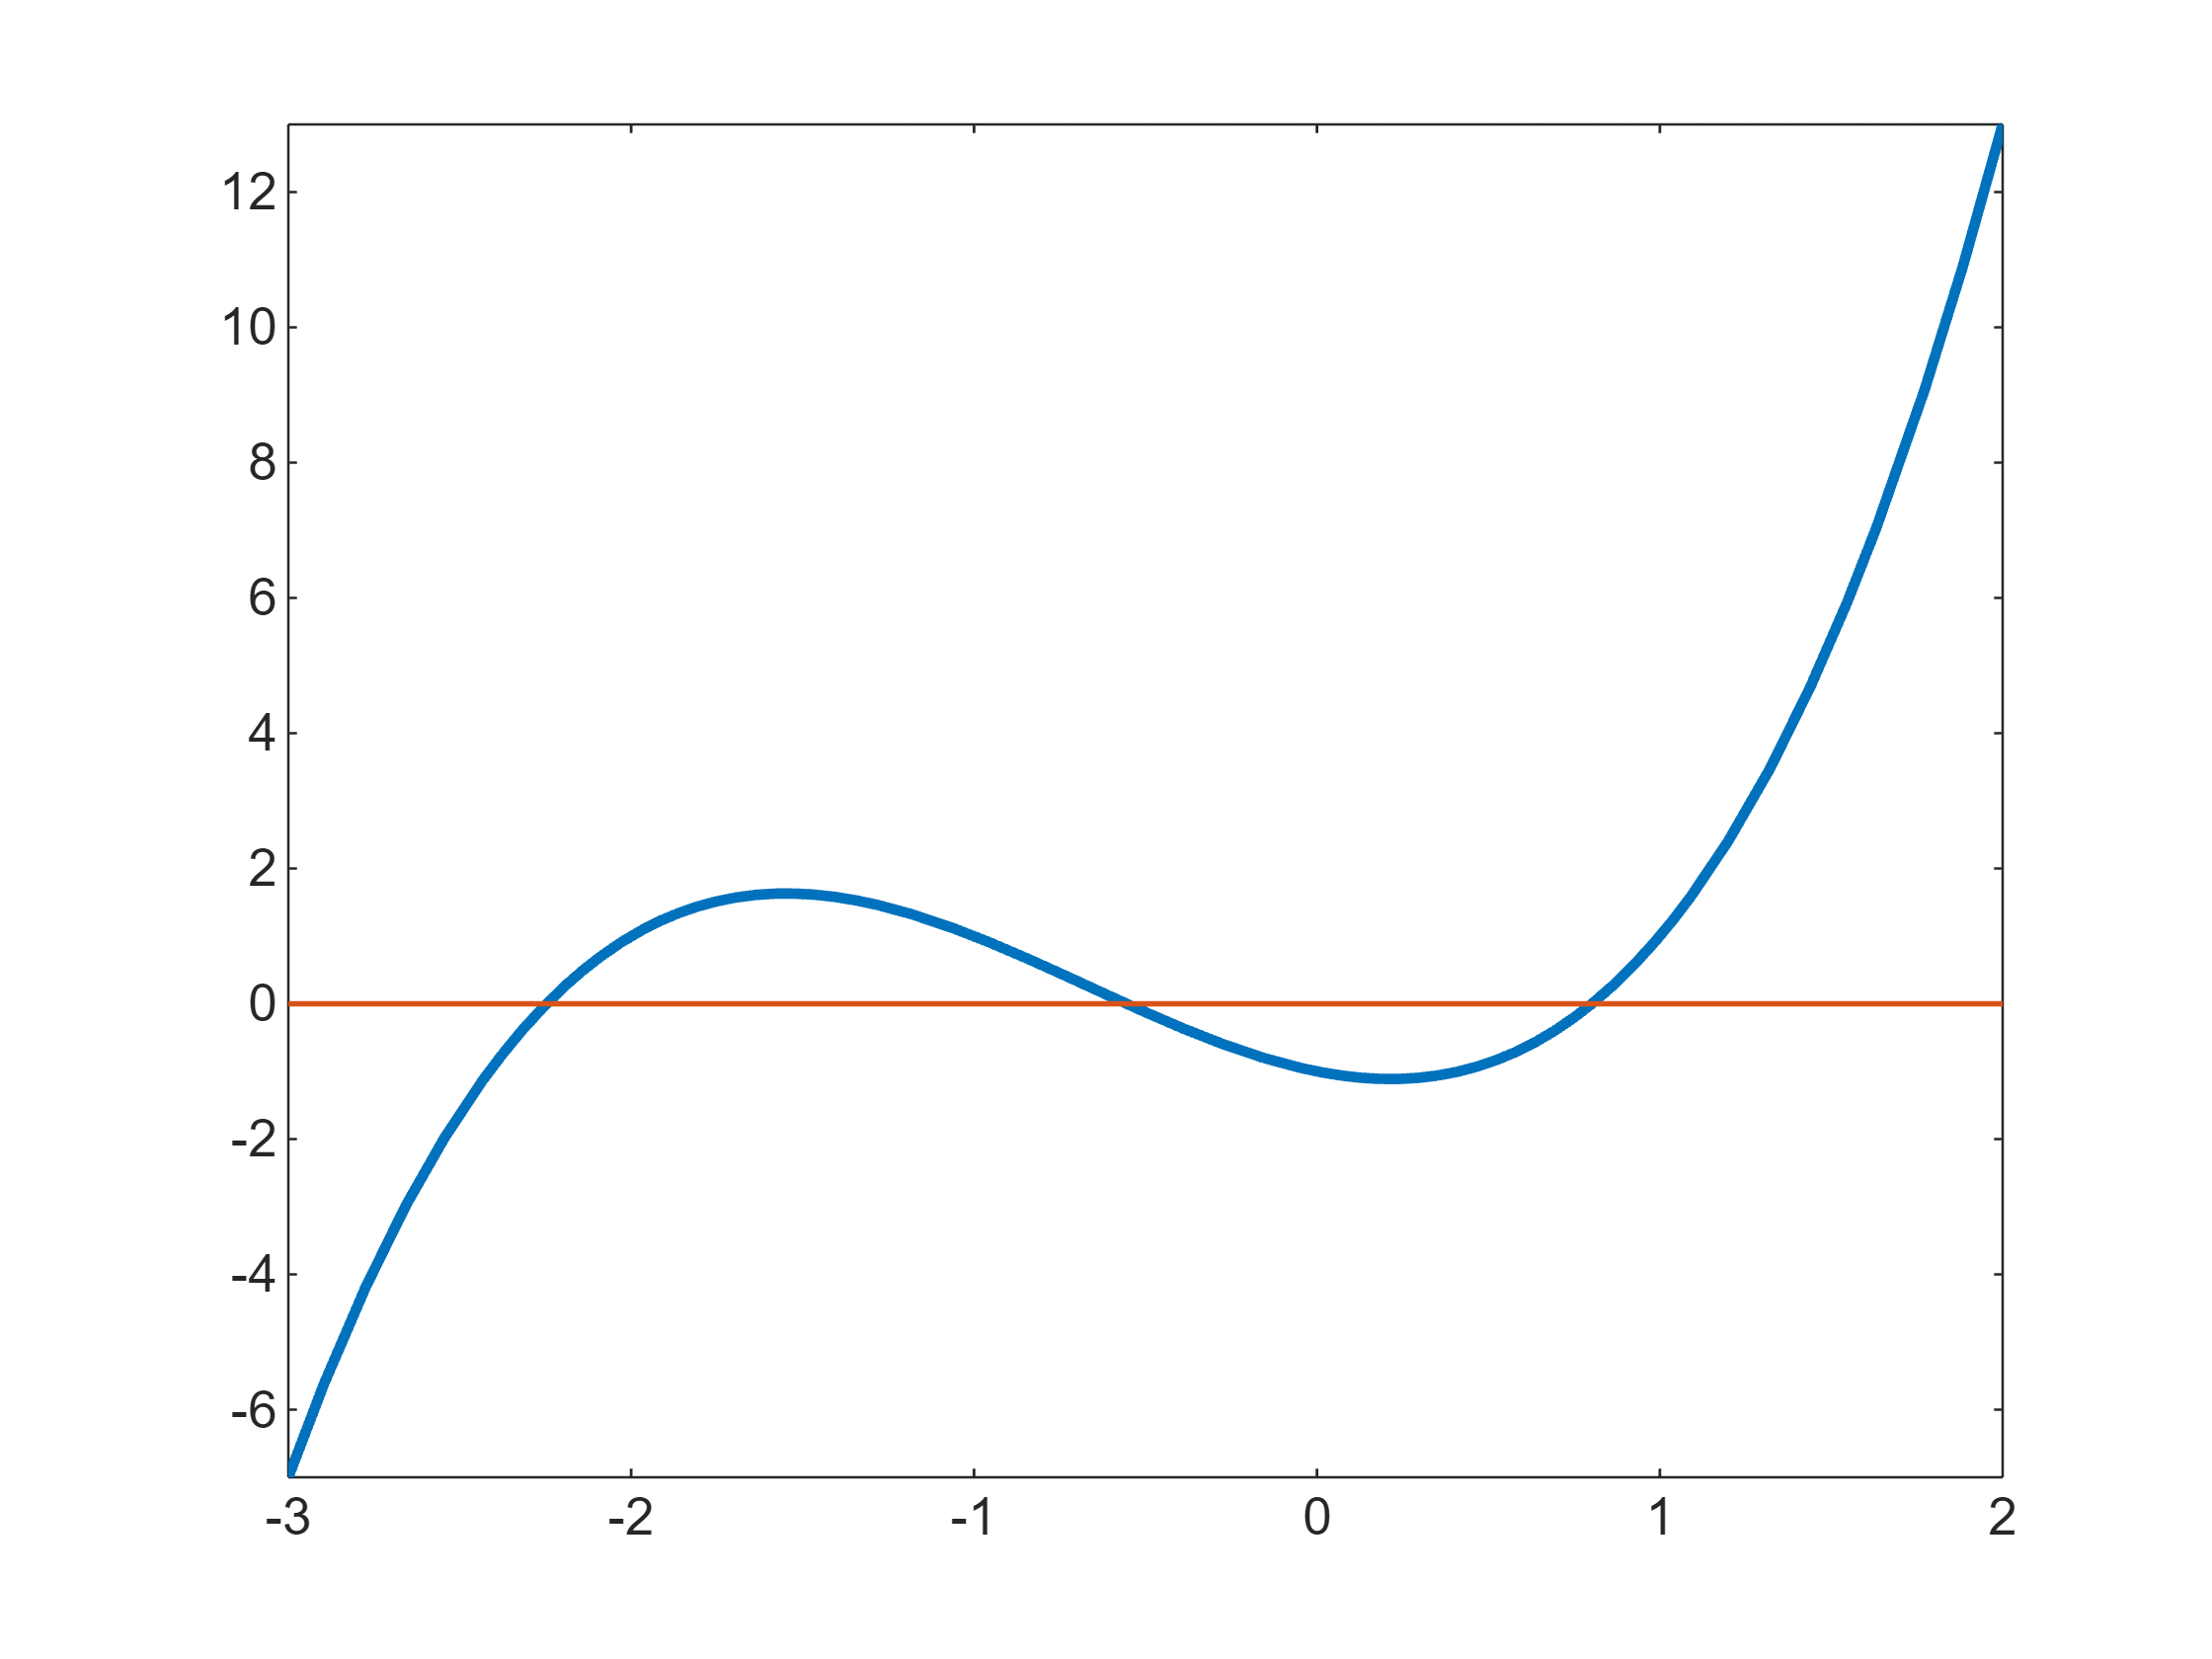

close all
f = @(x) x.^3 + 2*x.^2 - x - 1;
fplot(f,[-3,2],'LineWidth',2)
hold on
plot([-3 2],[0 0],'-','LineWidth',1)
hold off

f = @(x) x.^3 + 2*x.^2 - x - 1;
fzero(f,-3)  % -3附近的零点

ans = -2.2470

fzero(f,[0 2])  % 0和2之间的零点

ans = 0.8019

fzero(f,[-2 0])  % -2和0之间的零点

ans = -0.5550

fzero(f,[-3 2])

ans = -2.2470

% fzero(f,[-3 0])

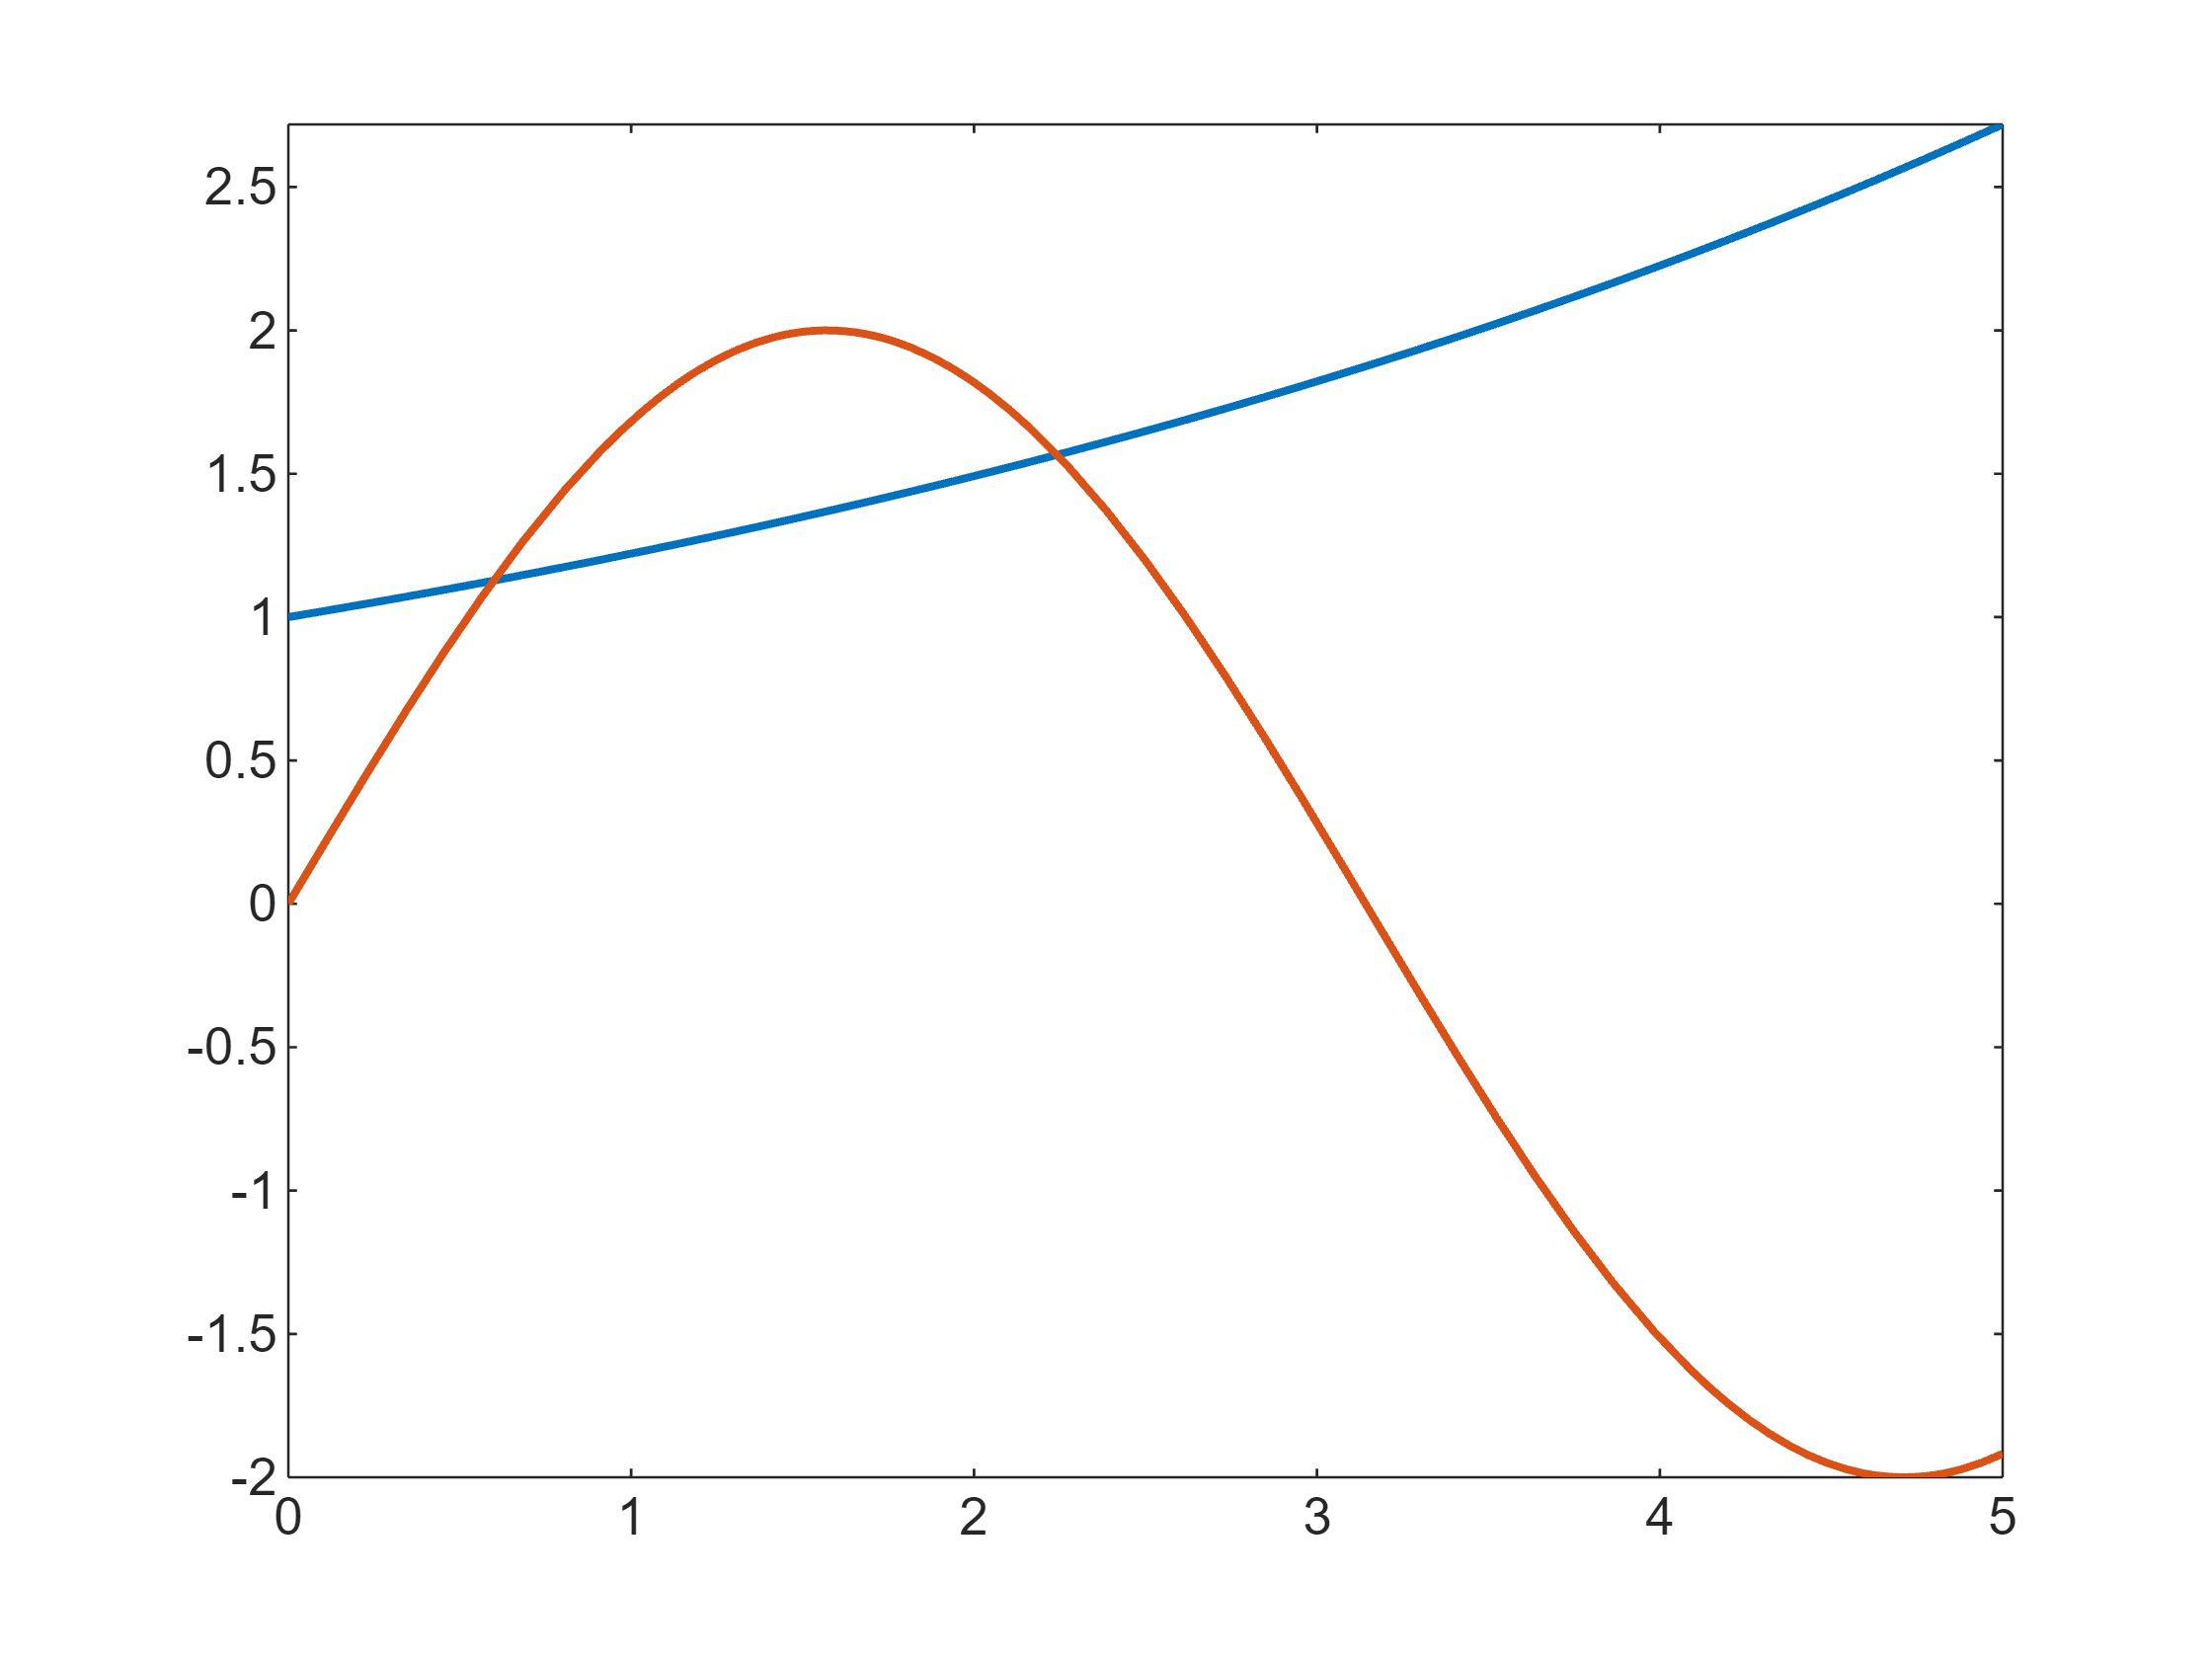

close all
fplot(@(x) exp(x/5),[0,5],'LineWidth',1.5)
hold on
fplot(@(x) 2*sin(x),[0,5],'-','LineWidth',1.5)
hold off

p = @(x) exp(x/5) - 2*sin(x);
fzero(p,[0 2])

ans = 0.5987

fzero(p,[2 3])

ans = 2.2422